# PARCISER - Projet 6.1 

## Génération de données simulées d'une SER

Le but est ici de se familiariser avec les données susceptibles d'être en sortie de l'analyseur de réseau, lors d'une série d'acquisition de la chambre anéchoïque de l'ENSTA.

La fonction gen_synth.m m'a été gracieusement donnée par le Dr. Comblet. Elle nécessite de poser plusieurs variables :

clear
%xs = [ones(1,10) (1:10) 10*ones(1,10) (10:-1:1) 5.5];
%ys =  [(1:10) 10*ones(1,10) (10:-1:1) ones(1,10) 5.5];

xs = [-3 -1 1 1 1 1 3 5 5];
ys = [0 0 -3 -1 1 3 0 -2 2];  %Vu dans le poly de Mr Kenchaf

amps = 10.^[ones(1,length(xs))];
map = [xs'/10 ys'/5 amps'];  %Coordonnées des points brillants, en forme d'avion, + amplitude
map2 = [[0 0.5 1]'  [0 0 0]'  [10 10 10]'];
c0 = 3e8;

Il faudra vérifier quelle est l'unité des distances à fournir à map, pour que cela soit cohérent, en attendant je considèrerai que c'est le mètre. Se rappeler aussi que la résolution en distance dépend de la largeur de bande. Ne pas prendre des points brillants dont la distance est inférieure à la résolution, mais aussi une cible dont les dimensions sont supérieures à la fenêtre d'ambiguïté.

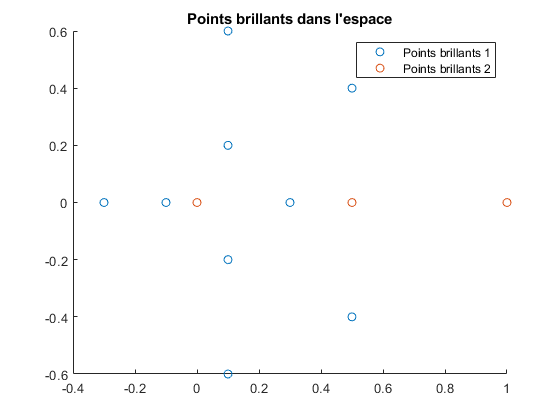

figure;
hold on
scatter(map(:,1),map(:,2),'DisplayName',"Points brillants 1")
scatter(map2(:,1),map2(:,2),'DisplayName',"Points brillants 2")
title("Points brillants dans l'espace")
legend
hold off

fmin = 8e9; fmax = 12e9; % fmin et fmax
th1 = -180; th2=180;  %angle min et max
nf = 200; nth = 6*360; %Nombre d'échantillons respectivement en angle, et en fréquence.
df = (fmax-fmin)/nf;
dth = (th2-th1)/nth;

freq = fmin:df:fmax-df;
angle = th1:dth:th2;

deltaR = c0/(2*(fmax-fmin));
Wd = c0/(2*df);
Wt = c0/(2*mean(freq)*dth*pi/180);

Ces variables sont posées en fonction des informations données par la page 15 de *Mesure de la SER*) 

Voyons ce que nous pouvons en faire.

sigc = gen_synth(map,fmin,fmax,nf,th1,th2,nth);  %Gpuarray() permet de faire les calculs sur le GPU, plus rapide.
sigc2 = gen_synth(map2,fmin,fmax,nf,th1,th2,nth);

sigc est une matrice de nf lignes, et nth colonnes.

Représentons la : 

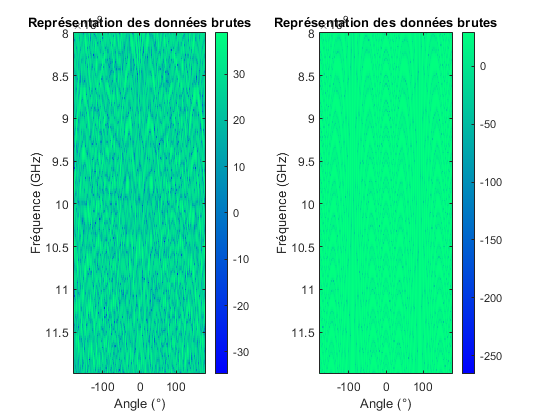

figure
subplot(1,2,1)
imagesc(angle,freq,20*log10(abs(sigc)));  % Notons bien que là, j'ai mis les angles, puis les fréquences, sciemment.
colormap winter
colorbar
title('Représentation des données brutes')
xlabel('Angle (°)')
ylabel('Fréquence (GHz)')
subplot(1,2,2)
imagesc(angle,freq,20*log10(abs(sigc2)));  % Notons bien que là, j'ai mis les angles, puis les fréquences, sciemment.
colormap winter
colorbar
title('Représentation des données brutes')
xlabel('Angle (°)')
ylabel('Fréquence (GHz)')

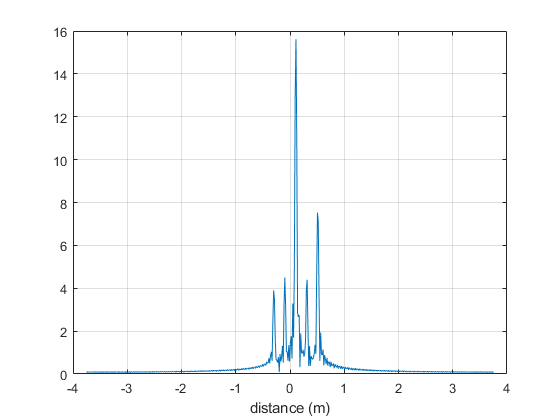

pro_dist=fftshift(ifft(sigc(:,1),512));  %Lorsque la cible est à -180°
distance=linspace(-Wd/2,Wd/2,length(pro_dist)); %
figure;plot(distance,abs(pro_dist),'DisplayName',"sigc");xlabel("distance (m)");ylabel("");hold on; grid on

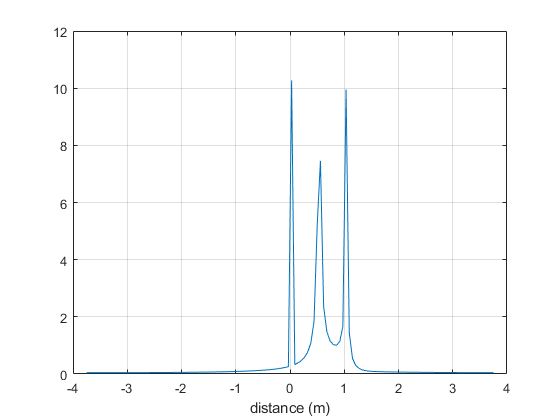

pro_dist2=fftshift(ifft(sigc2(:,1),128));  %Lorsque la cible est à -180°
distance=linspace(-Wd/2,Wd/2,length(pro_dist2)); %
figure;plot(distance,abs(pro_dist2),'DisplayName',"Zero Padded");xlabel("distance (m)");ylabel("");hold on; grid on

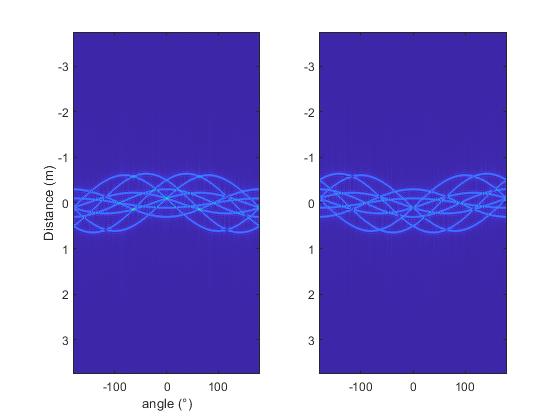

testsino=fftshift(ifft(sigc,2048));
sino=fftshift(ifft(sigc,2048),1);
figure;subplot(121);imagesc(angle,distance,abs(sino));xlabel("angle (°)"); ylabel("Distance (m)")
subplot(122);imagesc(angle,distance,abs(testsino))

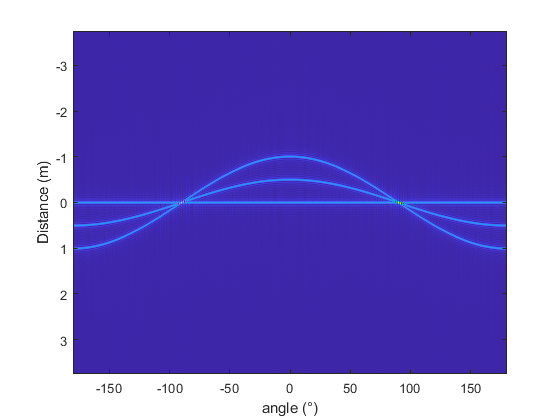

sino2=fftshift(ifft(sigc2,2048),1);
figure;imagesc(angle,distance,abs(sino2));xlabel("angle (°)"); ylabel("Distance (m)")

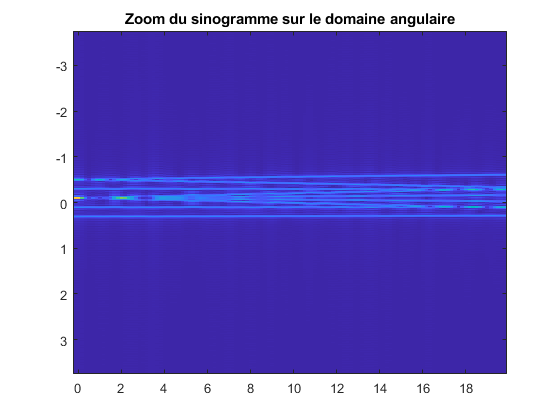

indice_debut = ceil(180*nth/360);
indice_fin = ceil(200*nth/360);
angles = indice_debut:indice_fin;
distanceT=linspace(-Wt/2,Wt/2,2048);
zoom = sino(:,angles);

figure
imagesc(angle(angles),distance,abs(zoom))
title("Zoom du sinogramme sur le domaine angulaire")

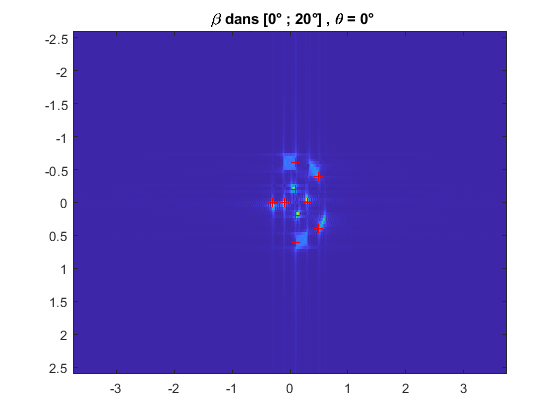

image = fftshift(fft(zoom,[],2),2);
figure
imagesc(distance,distanceT,fliplr(abs(image')))
title(" \beta dans [0° ; 20°] , \theta = 0°")
hold on;
plot(map(:,1),map(:,2),'+',"Color", 'red')

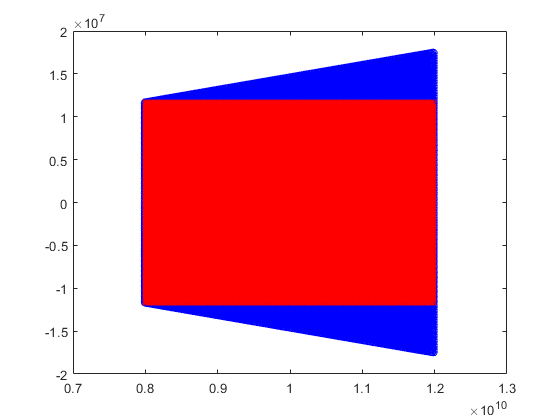

%coord cartesien
distanceT=linspace(-Wt/2,Wt/2,(indice_fin-indice_debut+1));
f1=min(freq);f2=max(freq);
t1=-dth/2;t2=+dth/2;
fx=linspace(f1,f2,length(freq));
fy=linspace(t1,t2,length(distanceT))*pi/180;
[xi,yi]=meshgrid(fx,fy);
%coord polaire
xip=xi.*cos(yi);
yip=xi.*sin(yi);
figure;plot(xip,yip,'ob');hold on

distanceT=linspace(-Wt/2,Wt/2,(indice_fin-indice_debut+1));
yic=linspace(yip(1,1),yip(length(distanceT),1),length(distanceT));
xifin=sqrt(fx(1,end)^2-yic(1,end)^2);
xic=linspace(f1,xifin,length(freq));
[fx,fy]=meshgrid(xic,yic);
plot(fx,fy,'xr');xlim([fmin-1e9 fmax+1e9])

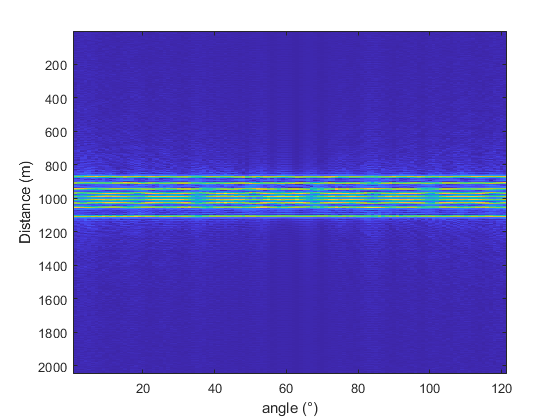

data=sigc(:,indice_debut:indice_fin);
datac=griddata(xip.',yip.',data,fx.',fy.','nearest');
sino3=fftshift(ifft(datac,2048),1);
figure;imagesc(abs(sino3));xlabel("angle (°)"); ylabel("Distance (m)")

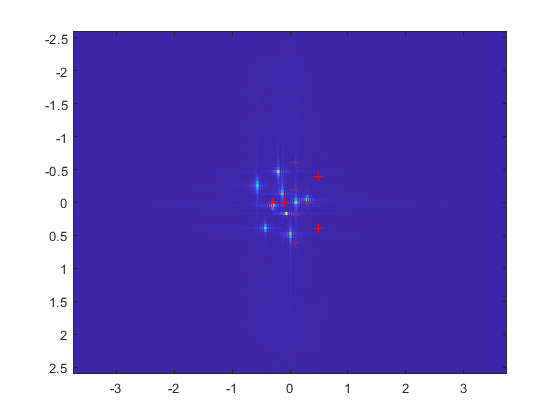

isar2 = fftshift(fft(sino3,[],2),2);
figure;imagesc(distance,distanceT,flipud(abs(isar2')));
hold on;
plot(map(:,1),map(:,2),'+',"Color", 'red')